%load('Data0223.mat');
load('FD.mat');
%load('PolarizedSimulationResult.mat');
addpath('../Library');
mli=9.988346*10^-27;  %kg
hbar=1.0545718*10^(-34); %SI
hh=2*pi*hbar;%SI Planck constant
omega=23.9*2*pi; %in rad/s
pixellength=1.44*10^-6; %in m
sigma0=0.215*10^-12/2; %in m^2
Nsat=330; %PI Camera
warning('off','all');
[ KappaTildeT_Pol, PTildeT_Pol,TTildeT_Pol] = IdealFermiEOS(  );
Xdash=0.1:0.05:6;
Ydash=1./Xdash;
[ KappaTildeT_U, PTildeT_U, TTildeT_U, ~, ~] = ...
    VirialUnitarity( );

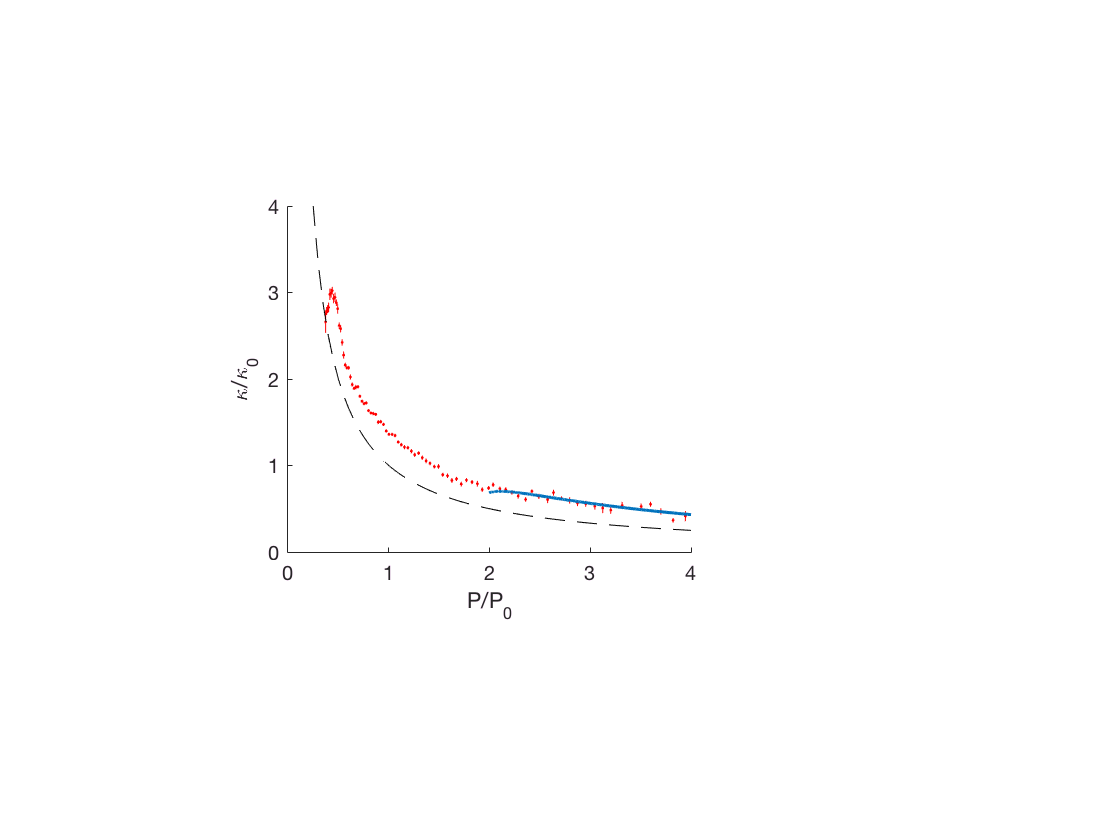

figure1=figure('Name','Figure');
axes1 = axes;
% p1=errorbar(PtMean,KtMean,KtStd);
% set(p1,'DisplayName','EoS Data from Experiment, Unitary',...
%     'MarkerSize',3,...
%     'MarkerFaceColor',[1 1 0],...
%     'Marker','diamond',...
%     'LineStyle','none',...
%     'Color',[1 0 0])

errorbar1derr_Z(PtMean,KtMean,KtStd,'Markersize',5,'MarkerFaceColor',[1 1 0],'Marker','.','LineStyle','none','Color',[1 0 0],'ErrLineWidth',0.5);

hold on
p2=plot(Xdash,Ydash,'k--');
set(p2,'DisplayName','KappaTilde*PTilde=1');
p3=plot(PTildeT_U,KappaTildeT_U);
set(p3,'DisplayName','Virial Expansion 3rd order','LineWidth',1.5,...
    'Color',[0 0.447058826684952 0.74117648601532]);
%p4=scatter(Ptbin_Pol,KtMean_Pol,'k*');
%set(p4,'DisplayName','Simulated Polarized Fermi Gas EoS')
%p5=plot(PTildeT_Pol,KappaTildeT_Pol,'linewidth',3);
%set(p5,'DisplayName','Ideal Polarized Fermi Gas EoS')
xlim([0,4]);
ylim([0,4]);
xlabel('P/P_0');ylabel('\kappa/\kappa_0');
set(axes1,'XTick',[0 1 2 3 4],'YTick',[0 1 2 3 4]);
set(axes1,'Units','inches','Position',[2 2 2.8 2.4]);
hold off
savefig(figure1,'EoS.fig');
print(figure1,'EoS','-dpdf');

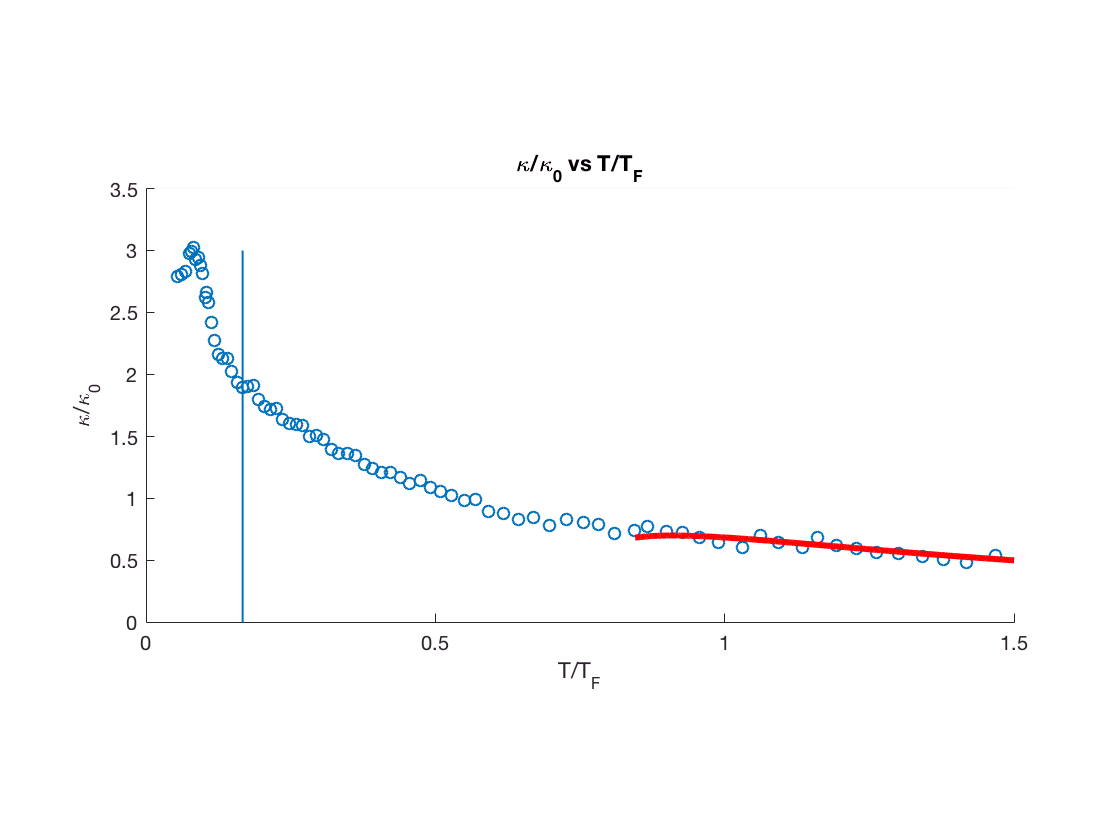

PtU=PtMean;
KtU=KtMean;
% the cutoff value for the pressure.
Ptcutoff=4;
Ttcutoff=interp1(PTildeT_U,TTildeT_U,Ptcutoff);

KtU(PtU>Ptcutoff)=[];
PtU(PtU>Ptcutoff)=[];
PtU(isnan(KtU))=[];
KtU(isnan(KtU))=[];

figure1=figure('Name','Figure');
axes1 = axes;
TtU=GetTTilde(PtU,KtU,Ttcutoff);
p1=scatter(TtU,KtU,'DisplayName','Experiment Data Unitary');
hold on
pbaspect([1 0.5 1])
plot(TTildeT_U,KappaTildeT_U,'r','linewidth',3,'DisplayName','Virial Expansion 3rd order');
xlabel('T/T_F');
ylabel('\kappa/\kappa_0')
title('\kappa/\kappa_0 vs T/T_F');
xlim([0,1.5])
p3=line([0.167,0.167],[0,3],'linewidth',1,'DisplayName','Tc=0.167');
%scatter(Tt_pol,KtMean_Pol,'DisplayName','Simulated Polarize Gas')
%plot(TTildeT_Pol,KappaTildeT_Pol,'DisplayName','Ideal Polarize Gas','linewidth',3)
%legend('show');
hold off

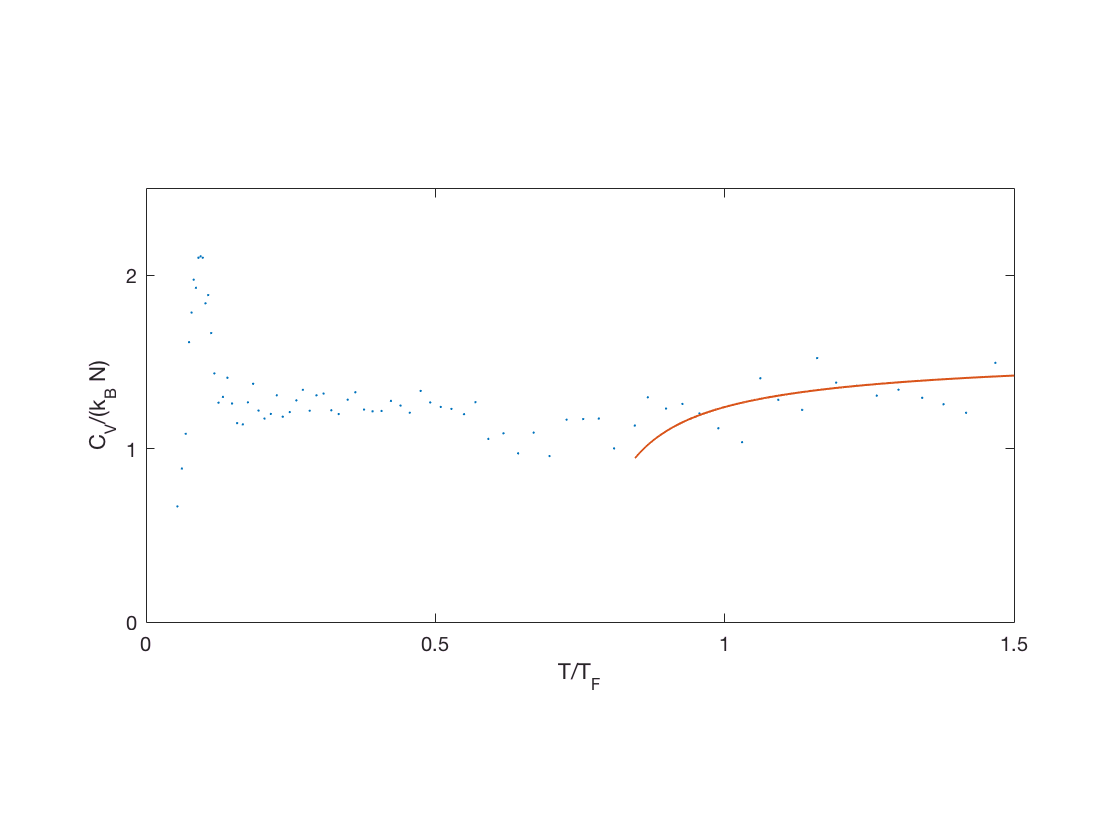

%%Try to get C_V with P,Kappa and T
Cvt_PKTU = GetCvTilde( PtU,KtU,TtU );
Cvt_PKTU = Cvt_PKTU;

figure1=figure('Name','Figure');
axes1 = axes;
plot(TtU,Cvt_PKTU,'.','DisplayName','Experiment Data Unitary with Some Cheating','markersize',3,'color',[0 0.45 0.74],'markersize',2);
hold on
CvTildeT_U=GetCvTilde( PTildeT_U,KappaTildeT_U,TTildeT_U );
plot(TTildeT_U,CvTildeT_U,'DisplayName','Virial Expansion','linewidth',1,'color',[0.85,0.33,0.1]);
pbaspect([1 0.5 1])
ylim([0,2.5]);xlim([0,1.5]);
xlabel('T/T_F');
ylabel('C_V/(k_B N)');
%scatter(Tt_pol,CvTilde_Sim_Pol,'k*','DisplayName','Simulated Polarized Gas');
%plot(TTildeT,CvTildeT_Pol,'DisplayName','Ideal Polarized Gas','LineWidth',3);
%title('C_V get from PTilde,kappaTilde,TTilde');
%line([0.167,0.167],[0,3],'linewidth',1,'DisplayName','Tc=0.167');
%legend('show');
hold off
set(axes1,'XTick',[0 0.5 1 1.5],'YTick',[0 1 2]);
%set(axes1,'Units','inches','Position',[2 2 4 4]);
savefig(figure1,'Cv.fig');
print(figure1,'Cv','-dpdf');

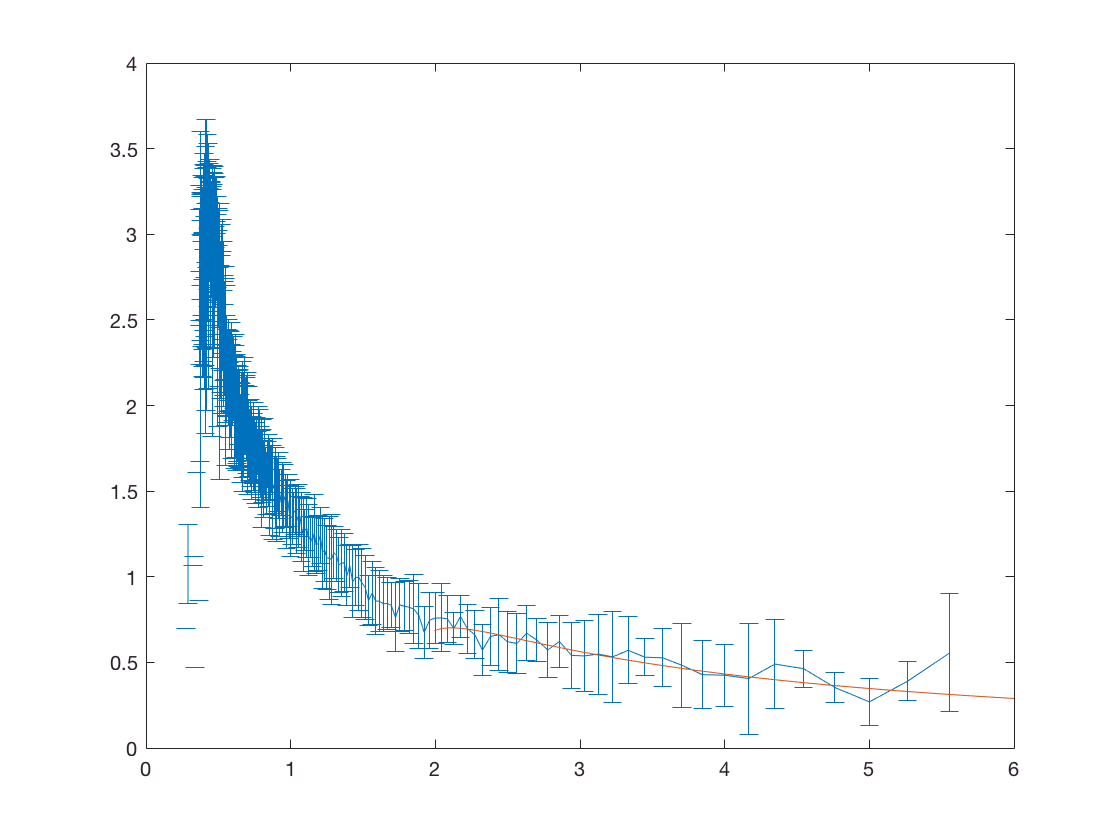

invPtlist=1./Ptlist;
[invPtbin,KtMean,KtStd]=BinLinear(invPtlist,Ktlist,0.15,4,0.01 );
Ptbin=1./invPtbin;
errorbar(Ptbin,KtMean,KtStd);
hold on
p3=plot(PTildeT_U,KappaTildeT_U);
hold off
xlim([0,6])

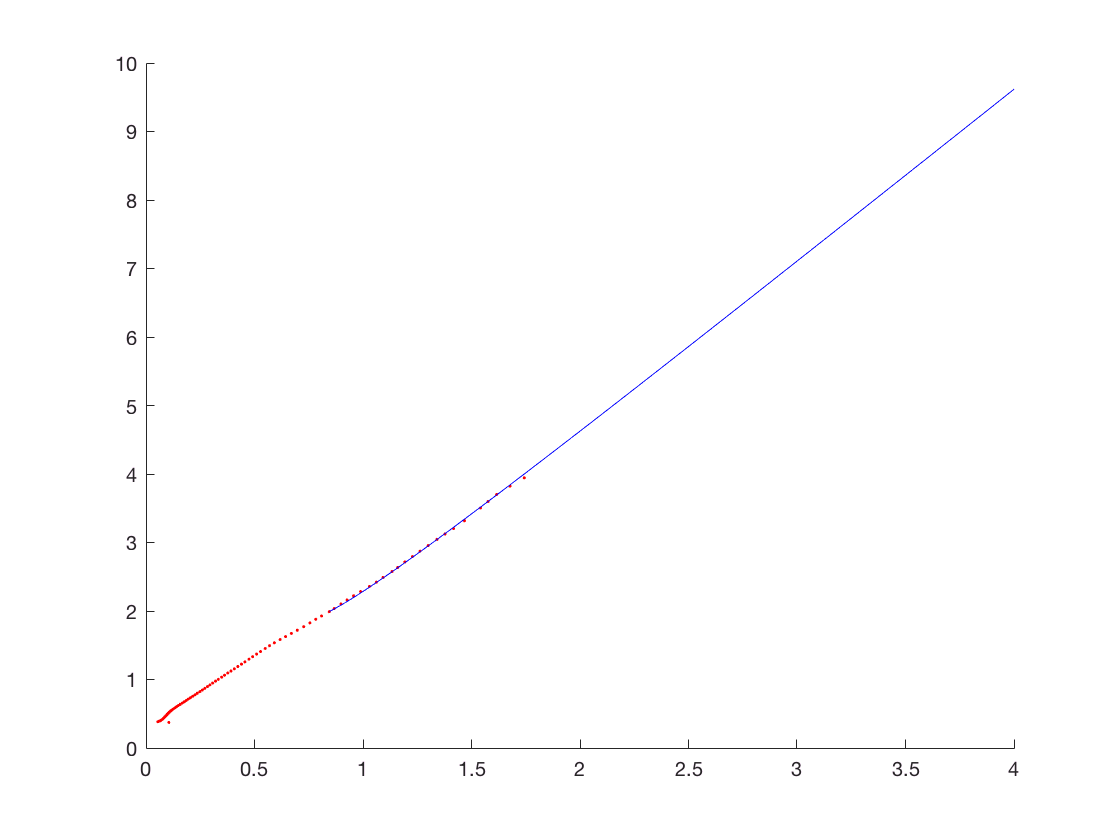

scatter(TtU,PtU,'r.');
hold on
plot(TTildeT_U,PTildeT_U,'b');
xlim([0,4]);
hold off